The Unit BasketBall

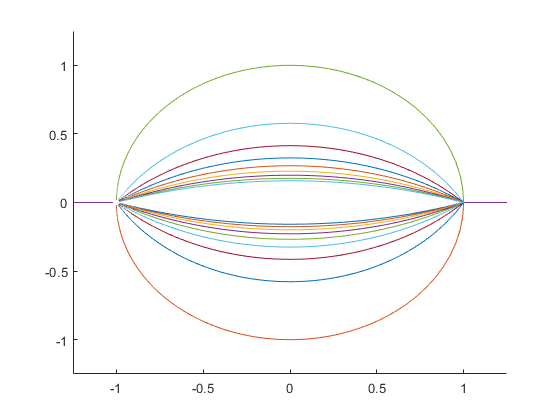

clear
clf
clc
close all
figure
scale = [-1.25,1.25,-1.25,1.25];
axis(scale)
hold on
mag = 200;
for k = -5:0.5:5
    if k == 0
        continue
    end
ang = pi/(2*k);
s = (0:0.1:mag) * exp(1j*(pi - ang));
Digital.MyBLT(s);
z = Digital.MyBLT(s);
plot(real(z),imag(z))
end
hold off

Design Example

%DF = Digital(Classification, Type, Amax, Amin, F)

In Class Example (My Attempt)

%Hz(num or den, coef, term)
Hzcoef(1,:,1) = [1,2,1];
Hzcoef(2,:,1) = [1,-0.9827,0.66648];
Hzcoef(1,:,2) = [1,1,0];
Hzcoef(2,:,2) = [1, -0.59771,0];

% Hz | z = e^(j*w*T) = e^(j*2*pi*f*T) = e^(j*2*pi*(f/fs))
fdivfs = 0:0.01:0.5;
z = exp(1j*2*pi*(fdivfs));

for n = length(Hzcoef(1,1,:))
Hznum = Hzcoef(1,1,n) + Hzcoef(1,2,n).*(z.^-1) +Hzcoef(1,3,n).*(z.^-2);
Hzden = Hzcoef(2,1,n) + Hzcoef(2,2,n).*(z.^-1) +Hzcoef(2,3,n).*(z.^-2);
Hzint(n,:) = Hznum./Hzden;
end
for n = length(Hzint(1,:))
    Hz = ones(length(z));
    for i = 1:length(z)
        Hz(i) = Hzint(i,n) * Hz(i);
    end
end

Index in position 1 exceeds array bounds (must not exceed 2).

plot(fdivfs,20*log10(abs(Hz)));grid


Prof Example

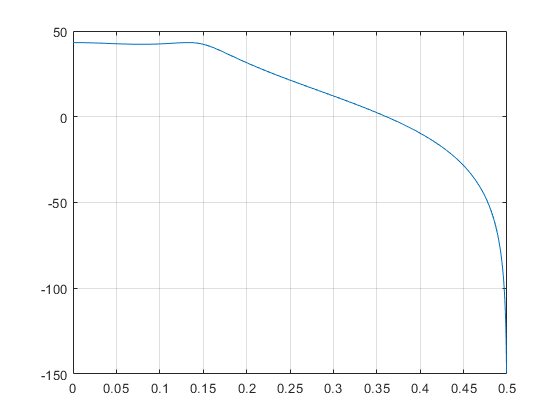

Hzcoef(1,:,1) = [1,2,1];
Hzcoef(2,:,1) = [1,-0.9827,0.66648];
Hzcoef(1,:,2) = [1,1,0];
Hzcoef(2,:,2) = [1, -0.59771,0];

K= 3.4385;
num = k* conv(Hzcoef(1,:,1),Hzcoef(1,:,2));
den = conv(Hzcoef(2,:,1),Hzcoef(2,:,2));

[H,w] = freqz(num,den,1024);

plot(w/(2*pi),20*log10(abs(H)));grid